LA_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/los-angeles-air-quality.csv";
SF_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/san-francisco-air-quality.csv";
SEA_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/seattle-air-quality.csv";

LA_AQ_Table = AQ_table(LA_Path);
SEA_AQ_Table = AQ_table(SEA_Path);

[LA_AQ_Table, SEA_AQ_Table] = same_dates(LA_AQ_Table, SEA_AQ_Table)

LA_AQ_Table = 2202×8 table
       date        pm25    pm10    o3     no2    so2    co     AQ 
    ___________    ____    ____    ___    ___    ___    ___    ___

    05-Jul-2020     96     193      43     17      1      5     96
    04-Jul-2020     49      65      43     13      1      3     49
    03-Jul-2020     44      26      45      9      1      2     45
    02-Jul-2020     50      22      39      6    NaN      1     50
    01-Jul-2020     34      27      34      8    NaN      1     34
    30-Jun-2020     25      20      30      6    NaN      2     30
    29-Jun-2020     19      12      28      5    NaN      1     28
    28-Jun-2020     51       9      23      3    NaN      1     51
    27-Jun-2020     37      19

SEA_AQ_Table = 2202×7 table
       date        pm25    o3     no2    so2    co     AQ 
    ___________    ____    ___    ___    ___    ___    ___

    05-Jul-2020     30     NaN    NaN    NaN    NaN     30
    04-Jul-2020     17      26      8     10      3     26
    03-Jul-2020     32      23     10    NaN      4     32
    02-Jul-2020     17      27     12    NaN      3     27
    01-Jul-2020     18      17     10    NaN      2     18
    30-Jun-2020     24      22     10    NaN      2     24
    29-Jun-2020     12      16      9      1      2     16
    28-Jun-2020     10      21      8      1      2     21
    27-Jun-2020     20      17      3      1      1     20
    26-Jun-2020    108      26     10      1      1    108
    25-Jun-2020     17   


diff = LA_AQ_Table.AQ-SEA_AQ_Table.AQ

diff =     66
    23
    13
    23
    16
     6
    12
    30
    17
   -62


Same_Value_pct = (length(diff(diff==0))/length(diff))*100

Same_Value = 21

LA_Higher_pct = (length(nonzeros(diff(diff>0))))

LA_Higher_pct = 1834

SEA_Higher_pct = (length(nonzeros(diff(diff<0))))

SEA_Higher_pct = 347

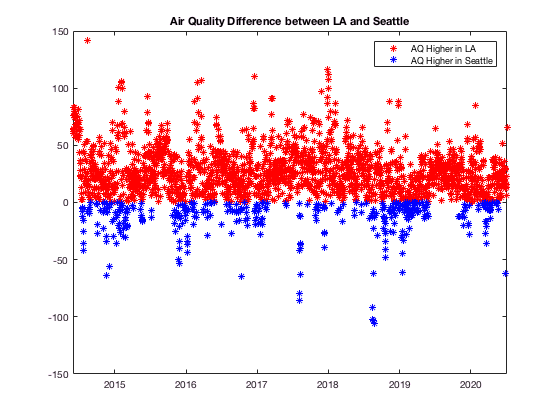


LA_Higher = zeros(length(diff), 1);
SEA_Higher = zeros(length(diff), 1);

for i = 1:length(diff)
    if diff(i)>0
        LA_Higher(i) = diff(i);
        SEA_Higher(i) = nan; 
    end 
    if diff(i)<0
        LA_Higher(i) = nan; 
        SEA_Higher(i) = diff(i);
    end 
end 

plot(LA_AQ_Table.date, LA_Higher, '*r')
hold on; 
plot(SEA_AQ_Table.date, SEA_Higher, '*b')
ylim([-150 150])
title('Air Quality Difference between LA and Seattle')
legend('AQ Higher in LA', 'AQ Higher in Seattle')

function AQ_Table = AQ_table(filename)
    % Read file into a table 
    AQ_Table = readtable(filename);
    % Create an air quality column (Max value of all columns per day)
    AQ_Col = max([AQ_Table.pm25, AQ_Table.o3, AQ_Table.no2, AQ_Table.so2, AQ_Table.co], [], 2);
    AQ_Table.AQ = AQ_Col;
    % Change dates to matlabs datetime object
    AQ_Table.date = datetime(AQ_Table.date,'InputFormat','yyyy/MM/dd');
    % Sort by date 
    [~,idx] = sort(AQ_Table.date, 'descend');
    AQ_Table = AQ_Table(idx,:);
end 

function [Table1_o Table2_o] = same_dates(Table1, Table2) 
    % Setting the length of both tables to that of the shorter table 
    max_len = min(length(Table1.date), length(Table2.date));
    Table1 = Table1(1:max_len, :);
    Table2 = Table2(1:max_len, :);
    
    % Finding all the common dates between both tables 
    [~, idx1, idx2] = intersect(Table1.date, Table2.date, 'stable');
    
    % Indexing the tables to only include common dates 
    Table1_o = Table1(idx1, :);
    Table2_o = Table2(idx2, :);
end 

